clear all
close all
clc

fun = inline('exp(2-x)+y^2','x','y');
dfunx = inline('-exp(2-x)','x','y');
dfuny = inline('2*y','x','y'); 
x0 = -2;
y0 = 2;
EPS = 0.00001; %error limit
p = 0.01; %step size
[x,y,n,point] = Tidu(fun,dfunx,dfuny,x0,y0,EPS,p)

x = 5.4543

y = 3.9172e-28

n = 3159

point =    -2.0000    2.0000   58.5982
   -1.4540    1.9600   35.4688
   -1.1377    1.9208   26.7413
   -0.9072    1.8824   21.8493
   -0.7242    1.8447   18.6468
   -0.5717    1.8078   16.3567
   -0.4408    1.7717   14.6216
   -0.3260    1.7363   13.2517
   -0.2236    1.7015   12.1362
   -0.1312    1.6675   11.2058


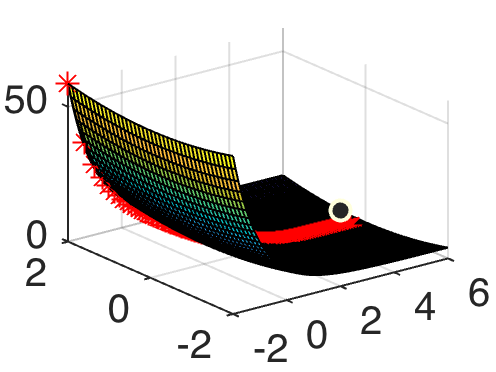


figure
x = -2:0.1:6;
y = -2:0.1:2;
[x,y] = meshgrid(x,y);
z = exp(2-x)+y.^2;
surf(x,y,z)    %绘制三维表面图形
hold on
plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
hold on
scatter3(point(:,1),point(:,2),point(:,3),'r','*');

function [x,y,n,point] = Tidu(fun,dfunx,dfuny,x,y,EPS,p)
    a = feval(fun,x,y);
    b = a+1;
    n=1;
    point(n,:) = [x y a];
    while (abs(a-b) >= EPS)  
      a = feval(fun,x,y);
      x = x - p*(feval(dfunx,x,y));
      y = y - p*(feval(dfuny,x,y));
      b = feval(fun,x,y); 
      n = n+1;
      point(n,:) = [x y b]; 
    end
end
